## Growth population model

close all;
clear all;
clc;

Parameters

load database\G_tree.mat
% load database\G_tree_single_plasmid.mat
% load database\G_tree_single_plasmid_parallel.mat

%testing the results
generationNumber = 1; % specify the generation you are interested in
totalProb = sum(G.Nodes.Probability(G.Nodes.Generation == generationNumber))

totalProb = 1

maxGen = max(G.Nodes.Generation);

% Store balances
protBalances = [];
auxBalances = [];
probabilities = [];
generations = [];

%parallel version
% First, initialize parallel pool if not already started
if isempty(gcp('nocreate'))
    parpool('local');
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.



protBalances = [];
auxBalances = [];
probabilities = [];
generations = [];

for gen = 0:maxGen
    % Extract nodes of the current generation
    nodesInGen = find(G.Nodes.Generation == gen)';
    numNodes = length(nodesInGen);

    % Temporary variables to store results from each parallel iteration
    protBalances_temp = zeros(1, numNodes);
    auxBalances_temp = zeros(1, numNodes);
    probabilities_temp = zeros(1, numNodes);
    generations_temp = gen * ones(1, numNodes);

    % Extract data before parallel loop
    populations = G.Nodes.Population(nodesInGen);
    nodeProbs = G.Nodes.Probability(nodesInGen);

    % Parallel loop
    parfor idx = 1:numNodes
        population = populations{idx};
        nodeProb = nodeProbs(idx);

        [prot_percent, aux_percent] = protoAuxoBalance(population);

        protBalances_temp(idx) = prot_percent;
        auxBalances_temp(idx) = aux_percent;
        probabilities_temp(idx) = nodeProb;
    end

    % Merge temporary results back into main arrays
    protBalances = [protBalances, protBalances_temp];
    auxBalances = [auxBalances, auxBalances_temp];
    probabilities = [probabilities, probabilities_temp];
    generations = [generations, generations_temp];
end

delete(gcp('nocreate'));

Parallel pool using the 'Processes' profile is shutting down.



%serial version
% for gen = 0:maxGen
%     % Extract nodes of the current generation
%     nodesInGen = find(G.Nodes.Generation == gen)';
% 
%     for nodeID = nodesInGen
%         population = G.Nodes.Population{nodeID};
%         nodeProb = G.Nodes.Probability(nodeID);
% 
%         [prot_percent, aux_percent] = protoAuxoBalance(population);
% 
%         % Store results
%         protBalances(end+1) = prot_percent;
%         auxBalances(end+1) = aux_percent;
%         probabilities(end+1) = nodeProb;
%         generations(end+1) = gen;
%     end
% end

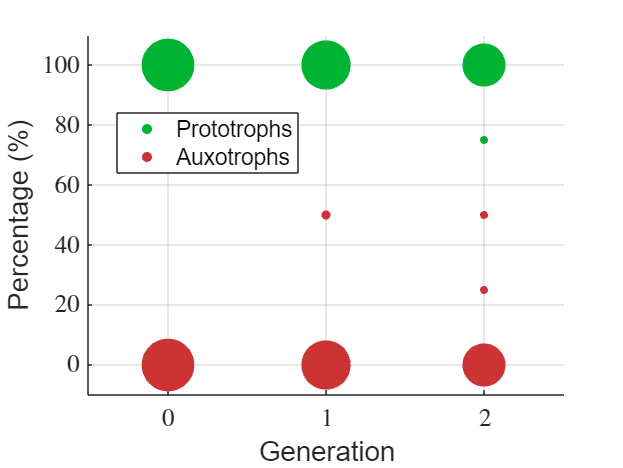


figure;
scatter(generations, protBalances, probabilities*1000, 'filled', 'MarkerFaceColor',[0 0.7 0.2]);
hold on;
scatter(generations, auxBalances, probabilities*1000, 'filled', 'MarkerFaceColor',[0.8 0.2 0.2]);

%Tick angles
X=0:maxGen;
set(gca, 'XTick', X);
set(gca, 'XTickLabel', 0:maxGen, 'TickLabelInterpreter', 'latex');
axis([-0.5 maxGen+0.5 -10 110])
xlabel('Generation');
ylabel('Percentage (%)');

% title('Protrophic vs Auxotrophic Balance per Node per Generation');
legend({'Prototrophs','Auxotrophs'},'Location','best');
set(gca,'FontSize',font)
grid on;

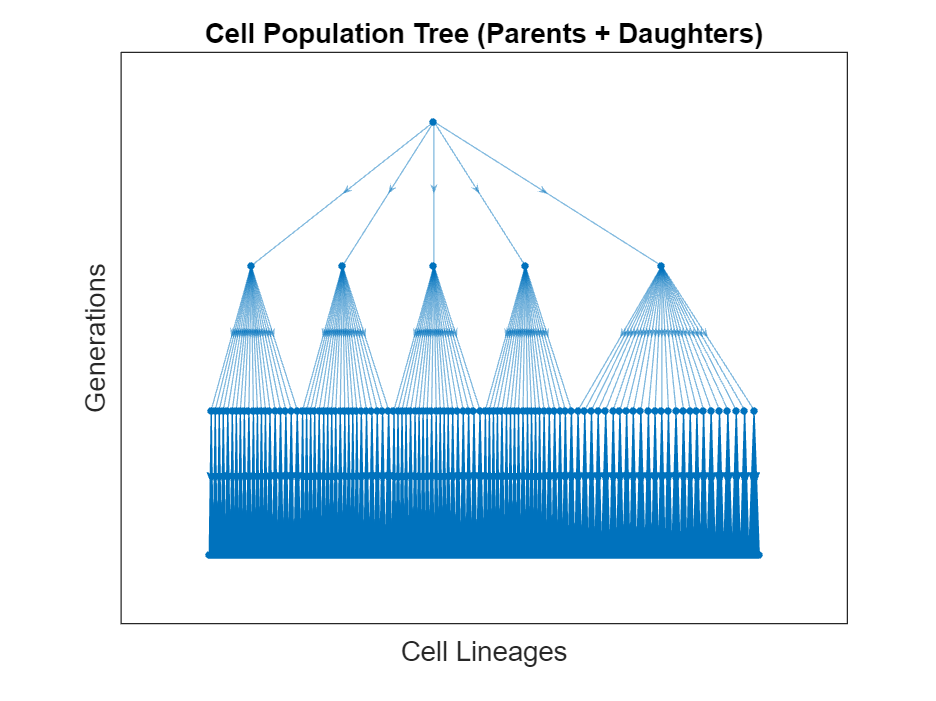


figure;
p = plot(G, 'Layout', 'layered', 'NodeLabel', '');

% for i = 1:numnodes(G)
%     label = G.Nodes.Label{i};
%     prob = G.Nodes.Probability(i);
%     fullLabel = sprintf('Pop:%s\nP=%.2e', label, prob);
%     labelnode(p, i, fullLabel);
% end

title('Cell Population Tree (Parents + Daughters)');
xlabel('Cell Lineages');
ylabel('Generations');

function binary = genotype2binary(genotype, numPlasmids)
    binary = de2bi(genotype, numPlasmids, 'left-msb');
end

function [populations, probs] = generateAllNewPopulations(parentPop, genotypes, p_s, numPlasmids)
    numParents = length(parentPop);
    possibleDaughters = cell(numParents,1);
    daughterProbs = cell(numParents,1);

    % Compute possibilities per parent
    for i = 1:numParents
        parentGeno = parentPop(i);
        validDaughters = genotypes(genotypes <= parentGeno);
        probs = zeros(length(validDaughters),1);
        for j = 1:length(validDaughters)
            probs(j) = segregationProbability(parentGeno, validDaughters(j), p_s, numPlasmids);
        end
        validDaughters = validDaughters(probs>0);
        probs = probs(probs>0);
        possibleDaughters{i} = validDaughters;
        daughterProbs{i} = probs;
    end

    % Generate all daughter combinations
    [allComb{1:numParents}] = ndgrid(possibleDaughters{:});
    daughterCombos = cell2mat(cellfun(@(x) x(:), allComb, 'UniformOutput', false));

    [allProbComb{1:numParents}] = ndgrid(daughterProbs{:});
    probCombos = prod(cell2mat(cellfun(@(x) x(:), allProbComb, 'UniformOutput', false)),2);

    % Combine parents and daughters explicitly
    numComb = size(daughterCombos,1);
    populations = zeros(numComb, numParents*2);
    for k = 1:numComb
        populations(k,:) = [parentPop, daughterCombos(k,:)];
    end
    probs = probCombos;
end

function [G, nextNodeID] = addPopulationNodes(G, parentID, genotypes, p_s, nextNodeID, numPlasmids)
    parentPop = G.Nodes.Population{parentID};
    parentProb = G.Nodes.Probability(parentID);
    currentGen = G.Nodes.Generation(parentID);

    [newPopulations, probs] = generateAllNewPopulations(parentPop, genotypes, p_s, numPlasmids);

    for i = 1:size(newPopulations,1)
        pop = newPopulations(i,:);
        popProb = parentProb * probs(i);
        label = mat2str(pop);
        G = addnode(G, table(nextNodeID, {pop}, currentGen+1, popProb, {label}, ...
            'VariableNames', {'ID', 'Population', 'Generation', 'Probability', 'Label'}));
        G = addedge(G, parentID, nextNodeID);
        nextNodeID = nextNodeID + 1;
    end
end


function prob = segregationProbability(parentGeno, daughterGeno, p_s, numPlasmids)
    parentBin = genotype2binary(parentGeno, numPlasmids);
    daughterBin = genotype2binary(daughterGeno, numPlasmids);
    lost = parentBin - daughterBin;

    if any(lost < 0)
        prob = 0; % impossible to gain plasmids
        return;
    end

    numLost = sum(lost);
    
    if numLost == 0
        % Case: no plasmid lost. Probability = 1 - sum(other losses)
        % Compute sum of other cases explicitly
        prob_sum = 0;
        if (sum(parentBin)==0)%in the case that the parentBin is all auxotrophic
            prob=1; %an all auxotrophic cell always produces an all auxotrophic cell
        else
            for n = 1:sum(parentBin)
                num_cases = nchoosek(sum(parentBin), n); % number of ways to lose n plasmids
                prob_sum = prob_sum + num_cases * (p_s^n);
            end
        end
        prob = 1 - prob_sum;
    else
        prob = p_s^numLost;
    end
end

function [prot_percent, aux_percent] = protoAuxoBalance(population)
    prototrophs = sum(population == 15);
    total = length(population);
    prot_percent = prototrophs / total * 100;
    aux_percent = 100 - prot_percent;
end

